### This experiment corresponds to the Section 7.3 of the Thesis

For the smooth running of the experiment make sure to have python (version 2.7) installed and then also have the package 

installed mentioned in the file BEAY_IN_OUT1.

Determine and give input to the following for the Parameters and response data ids. 

The conversion of the data to respective format will be then done for the compatibility of the corresponding software. This is corresponding to the 7.3.1 and 7.3.2 of the Thesis**.**

parameters= {'BARE','Zone1'};
x0 = [1.5, 2.5];
%x0 = [2.0, 3.33];
%tru_sol_x0 = [2.0, 3.33333, 7.0, 7.0, 0.66667];

calibration_data_type = {'voltage', 'normal current density'};

IPs_IDs1 = [32866,32886,32870,32874,32882,32846,32850,32878,32854 ,  32858,32890,32862];
%IPs_IDs1 = {32866,32886,32870,32874,32882,32846,32850,32878,32854 ,  32858,32890,32862};

IDs_current_density = [ 7400, 16000, 19860, 23802];
%IDs_current_density = { 7400, 16000, 19860, 23802};

IDs = {py.list(IPs_IDs1), py.list(IDs_current_density)};
%IDs = {py.list(num2cell(IPs_IDs1)), py.list(num2cell(IDs_current_density))};

IDs_mat_arr = {IPs_IDs1, IDs_current_density};

IDs_types = {'Internal Points', 'Mesh Points'};

### **Design of Experiments for Surrogate building (Thesis section 7.3.3)**

%IDs = meas_data_Internal_Points(:,1);

%DOE_range1 = [1.0, 2.5; 3.0, 3.8]; 
DOE_range1 = [1.0, 2.5; 3.0, 3.8]; 

%DOE experiment for 2 varaibles using Central Composite Design
Central_composite_points = ccdesign(2, 'type', 'inscribed', 'center' , 1);


DOE_sample_points1 = reverse_normalization(Central_composite_points, DOE_range1);

parameters_np_array1 = convert_arr_to_python_2d_list(DOE_sample_points1);
%DOE_sample_points = [DOE_sample_points ;reverse_normalization(Central_composite_points, DOE_range2)];

### **Navigate the Simulation related folder, the seed folder that contains the BEASY simulation input file and collection dir will be holding the simulation results during the experimentation process. **

root_folder = 'D:\DOE_nd_data_generation\Multilinear_pol_curves\Parameter_BARE_Zone1';

simulation_seed_folder = fullfile(root_folder,'Initial_files');
%simulation_seed_folder  = "C:\Users\msapkota\EXPERIMENT\DOE_nd_data_generation\Model_updated_linear\Parameter_BARE_Zone1\Initial_files1";

collection_dir = fullfile(root_folder,'Simulation_results');

#### Data collection as mentioned by above DOE and from tthe simulation

snapshots_py = py.BEASY_IN_OUT1.snapshots_for_given_parameters_and_IDs(py.list(parameters), parameters_np_array1, ...
    py.list(IDs), py.list(calibration_data_type), simulation_seed_folder, collection_dir, py.list(IDs_types));

snapshots = double(snapshots_py);

%writematrix(snapshots, 'snapshots_matrix.csv');

#### Surrogate Model from the simulation snapshots data above, that takes input of the sample points and output as the response data, 

#### the last number represents the polynomial degree. (Thesis correspondance 7.3.4)

surrogates = response_surface(DOE_sample_points1, snapshots, 2);
%}

surrogates{1}


     Linear model Poly22:
     ans(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2
     Coefficients (with 95% confidence bounds):
       p00 =      -865.1  (-1071, -659.3)
       p10 =       121.5  (90.8, 152.3)
       p01 =      -54.89  (-169.2, 59.43)
       p20 =      -14.38  (-19.12, -9.627)
       p11 =      -3.448  (-11.04, 4.144)
       p02 =       4.908  (-11.79, 21.6)



Performnace test for the surrogate (Thesis section 7.3.4)

testing_par = [1.49, 3.21];

test_dict =  py.BEASY_IN_OUT1.get_response_data_for_IDs_and_input_parameters(parameters, testing_par, ...
    simulation_seed_folder, ...
    collection_dir, py.list(calibration_data_type), py.list(IDs), py.list(IDs_types));

test_simulation_data = convert_pydict2data(test_dict,1);

test_surrogate_output = output_from_surrogates(testing_par, surrogates,[length(IDs{1}), length(IDs{2})]); 

normalised_mean_sq_diff(test_simulation_data, test_surrogate_output, calibration_data_type, [2 1])

ans = 0.0014

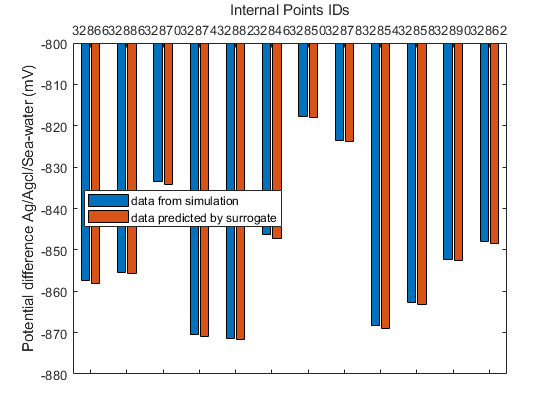

figure;

ax = gca;

data_count = 1;
difference_in_bar_chart(ax,test_simulation_data{data_count}, test_surrogate_output{data_count}, ...
    {'data from simulation','data predicted by surrogate'});

if isequal(data_count, 2)
    
    ylabel('Normal Current Density (mA/m^2)');
    ylim([-4000 -2000]);
else
    ylim([-880 -800]);
    ylabel(ax, 'Potential difference Ag/Agcl/Sea-water (mV)');
end
xlabel(strcat(IDs_types{data_count}, ' IDs'));

#### Loading the Calibration data. 

The data given in excel file with the data associated to the IDs mentioned above can be directly read. In this case as the data is

 obtained from an artifical simulatin with some noise introduction after having the simulation data.)

calib_dir = fullfile(root_folder,'Calibration_data2');

calib_data_file_err_inc = 'data_with_error_MP_IDs_Ncd.xlsx';

%%{
if ~isfile(fullfile(calib_dir, calib_data_file_err_inc))
    all_position_dict = py.BEASY_IN_OUT1.get_output_data_for_IDs_from_simulation_folder(calib_dir, ...
        'BU_Jacket_newCurves', py.list(calibration_data_type),  py.list(IDs), py.list(IDs_types));
    all_position_data = convert_pydict2data(all_position_dict,0);
    introduce_error_and_write_file( {IPs_IDs1.', IDs_current_density.'},all_position_data, calib_dir, ...
        calib_data_file_err_inc,1);
end
%model_out = output_from_surrogates([2.0, 3.0], surrogates, [17,6]);
%}
calib_data_inc_error = data_from_tables2(fullfile(calib_dir, calib_data_file_err_inc), IDs_mat_arr, 3);
calib_data_no_error = py.BEASY_IN_OUT1.get_output_data_for_IDs_from_simulation_folder(calib_dir, ...
    'BU_Jacket_newCurves', py.list(calibration_data_type),  py.list(IDs), py.list(IDs_types));
calib_data_no_error = convert_pydict2data(calib_data_no_error,0);

#### Parameter Estimation with surrogate (Thesis 7.3.5)

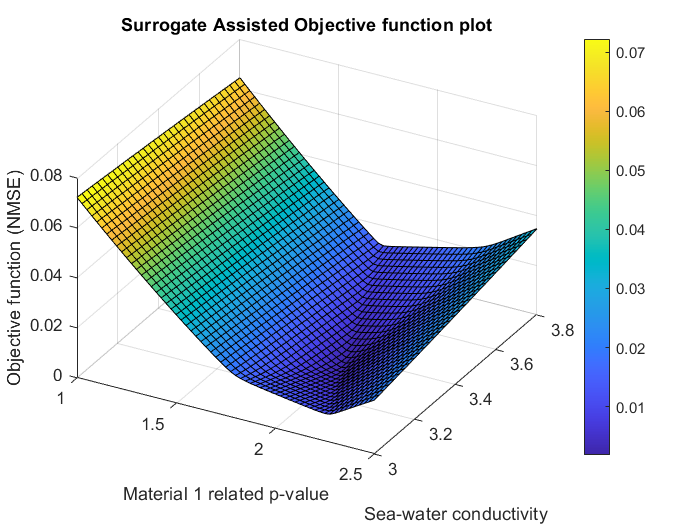

figure;

ax = gca;

metric = 'nmsq';

[plot_data,f_min, min_out_pos1] = plot_objective_with_surrogates(ax, DOE_range1, surrogates, calib_data_inc_error, ...
    metric, calibration_data_type, [length(IDs{1}), length(IDs{2})],[0.66, 0.33], [0.025,0.025]);

output_from_surrogate = output_from_surrogates(min_out_pos1, surrogates,[length(IDs{1}), length(IDs{2})]); 

xlabel('Material 1 related p-value');
ylabel('Sea-water conductivity');

min_out_pos1

min_out_pos1 =     2.0000    3.3500


testing_par_value = min_out_pos1
%testing_par_value = [2.000, 3.35];

    solution_dict =  py.BEASY_IN_OUT1.get_response_data_for_IDs_and_input_parameters(parameters, testing_par_value, ...
        simulation_seed_folder, collection_dir, py.list(calibration_data_type), py.list(IDs), py.list(IDs_types));

    solution_data = convert_pydict2data(solution_dict,1);

    normalised_mean_sq_diff(solution_data, calib_data_inc_error, calibration_data_type, [2 1])

ans = 0.0052

#### Solution Performance analysis

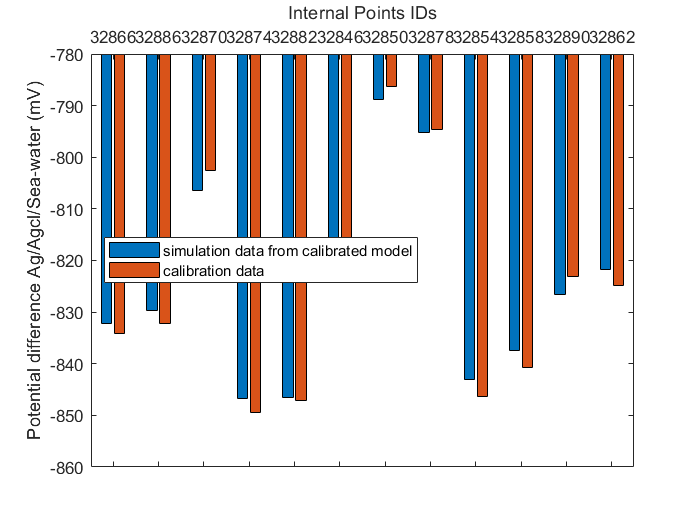

figure;

ax = gca;

data_count = 1;
difference_in_bar_chart(ax,solution_data{data_count}, calib_data_inc_error{data_count}, ...
    {'simulation data from calibrated model','calibration data'});

if isequal(data_count, 2)
     ylabel('Normal Current Density (mA/m^2)');
    ylim([-2400 -1200]);
else
    ylim([-860 -780]);
    ylabel(ax, 'Potential difference Ag/Agcl/Sea-water (mV)');
end
xlabel(strcat(IDs_types{data_count}, ' IDs'));

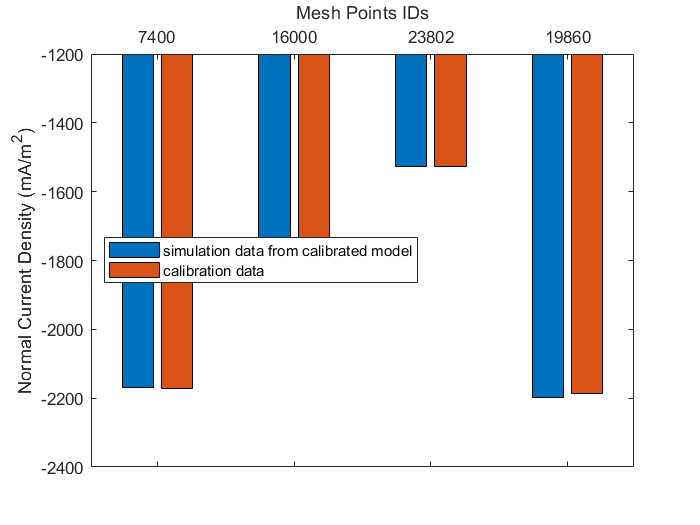

figure;

ax = gca;

data_count = 2;
difference_in_bar_chart(ax,solution_data{data_count}, calib_data_inc_error{data_count}, ...
    {'simulation data from calibrated model','calibration data'});

if isequal(data_count, 2)
    %difference_in_bar_chart(ax,solution_data{data_count}, calib_data_inc_error{data_count},{'simulation data from calibrated model','calibration data', 'difference'});

    ylabel('Normal Current Density (mA/m^2)');
    ylim([-2400 -1200]);
else
    ylim([-860 -780]);
    ylabel(ax, 'Potential difference Ag/Agcl/Sea-water (mV)');
end
xlabel(strcat(IDs_types{data_count}, ' IDs'));

%}

Plot for the sample points

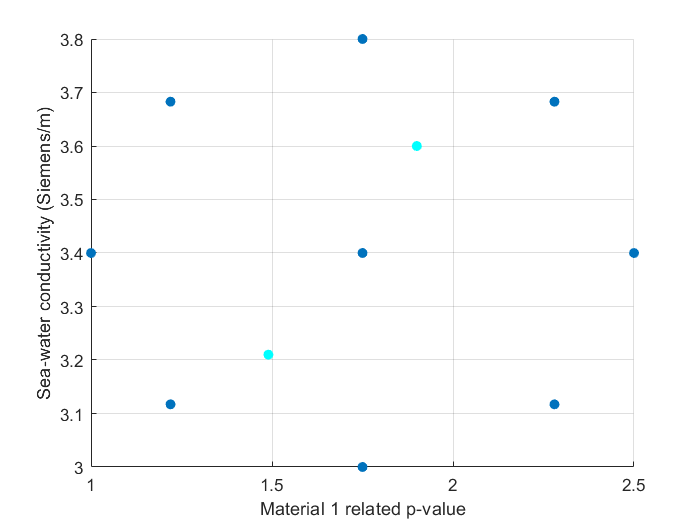

%solution_points = [0.02 0.02; 0.085 0.06; 0.145 0.105];
figure;
%scatter( previous_sample_points(:,1),  previous_sample_points(:,2), 'filled');

scatter( DOE_sample_points1(:,1),  DOE_sample_points1(:,2), 'filled');
hold on;
%scatter( DOE_sample_points20(:,1),  DOE_sample_points20(:,2), 'filled', 'g');
%scatter( DOE_sample_points20(1:4,1),  DOE_sample_points20(1:4,2), 'filled', 'g');
%scatter(  added_sample_Points(:,1),  added_sample_Points(:,2), 'filled', 'g');
testing_pars = [1.49, 3.21; 1.9 3.6];
scatter( testing_pars(:,1), testing_pars(:,2), 'filled', 'c');

%scatter(solution_points(:,1), solution_points(:,2), 'filled','c');
xlabel('Material 1 related p-value');
ylabel('Sea-water conductivity (Siemens/m)');

grid on;

function de_normaised_data = reverse_normalization(normalised_data, value_ranges)

de_normaised_data = zeros(size(normalised_data));

for i = 1:size(normalised_data, 2)
    
    de_normaised_data(:,i) = value_ranges(i,1)+ diff(value_ranges(i,:))/2 * (normalised_data(:,i)-(-1));
    
end
end